# HO-SVD

clear;
clc;

format short g;

% Set seed
% rng(197);
% rng(123);
% rng(111);
rng(1);

**Continuous Complex System**

We consider the 2-parameter complex system, where $f(x_1,x_2)=\Lambda(x_1,x_2)(e \times sin(8x_1) + 5 sin(3x_2))$ when $x_1 < x_2$ and $f(x_1,x_2)=(1-\Lambda(x_1,x_2))(e \times sin(8x_1) + 5 sin(3x_2))$ when $x_1 \geq x_2$. Furthermore, $\Lambda(x_1,x_2)$ is an exponential smoothing term, which smooths the transition, where $x_1 \sim x_2$.

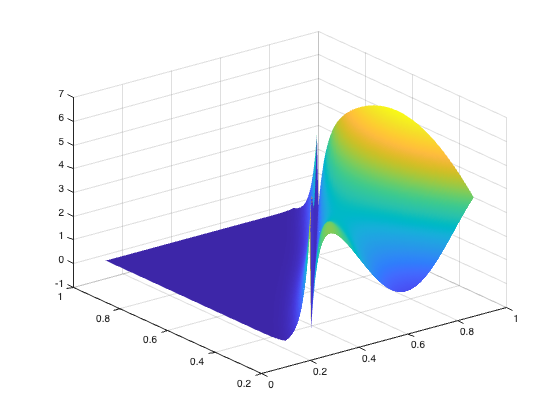

%% Create Space
load Space_Slanted_Border_Function.mat;

surf(X,Y,Space,'EdgeColor','none')

**Default parameters**

In our experiments,

- We set the default per time stamp sampling budget $B^t$ to **0.02%** of the volume of the space.

- The target rank for HO-SVD is set to **25%** of the size of the parameter space.

- The default exploration probability for BFF-RS and GFF-RS is set to **0.25**.

In this particular case, we set the step budget size to **8** new samples.

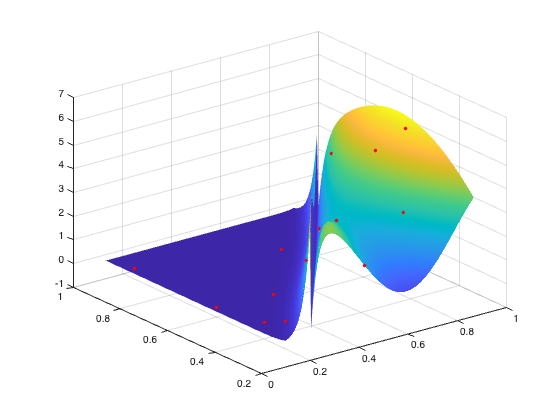

% Volume of the space
dimX = size(X,1);
dimY = size(Y,1);
volume = dimX * dimY;

% Initial budget
budget = ceil(0.0002 * volume);

% Budget for next iterations
new_budget = 8;

alpha = 0.5;

% Initial random samples
samples = randi(dimX,budget,2);
[x,y,s] = create_samples(X,Y,Space,samples);

draw_samples(X,Y,Space,x,y,s);

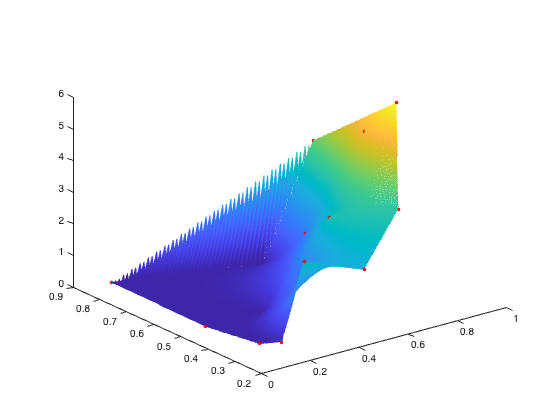

draw_interpolation(X,Y,x,y,s);

With only 14 points, the approximation to the original function is very bad.

T = sptensor(samples,s',[dimX dimY]);


eps = 0.0002; %Tolerance
%% HOSVD estimation
T_full = full(T);  % Convert T to a (dense) tensor
T_doub = double(T_full);
decom = hosvd(T_full,2*sqrt(eps));

Computing HOSVD...
Size of core: 8 x 8
||X-T||/||X|| = 0.0140773 <=0.028284 (tol)



%Factor matrices (U,V,W) and core tensor
core=decom.core;
G=double(core);
U=decom.U{1};
V=decom.U{2};
% W=decom.U{3};

## SAMPLE SELECTION STRATEGIES

% decom_doub = double(decom);
tensor_recon = full(decom);

fit = calculate_fit(T_full,decom);

In this case, we calculate the degree of fit of each pivot (actually it is the loss) as:


$$loss(x^t) = abs\left(\frac{x^t-\hat{x}^t}{x^t}\right)$$


Where $x^t$ is the pivot entry and $\hat{x}^t$ is the reconstructed version of that entry.

### BAD FIT FIRST

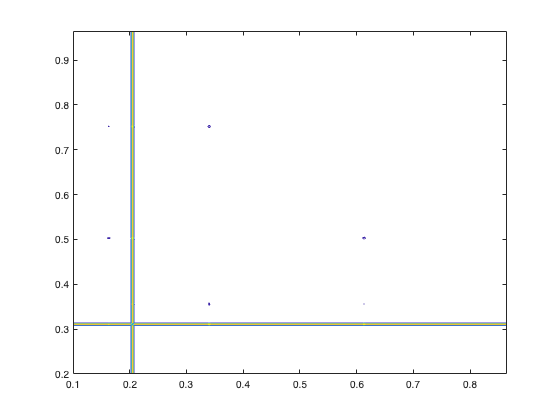

[row,col,maxvalues,losses,prob_mat] = create_new_samples(X,Y,Space, ...
    T_full,tensor_recon,samples, ...
    new_budget,'bff');
contour(X,Y,prob_mat)

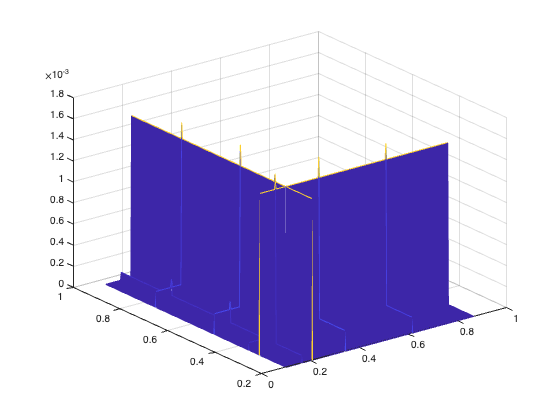

mesh(X,Y,prob_mat)

disp(losses')

   5.3312e-06
     0.014005
            0
            0
      0.14173
            0
            0
            0
     0.018251
            0
            0
            0
    0.0068646
   1.5309e-11



[row col maxvalues]

ans =           102           36    0.0017345
           38           81    0.0017345
          185           36    0.0016884
           38          172    0.0016884
           38           22     0.001611
           53           36     0.001611
           38            8    0.0015366
          107           36    0.0015366


We see that all the new samples are in the same row. This may be due to the fact that the chosen space is not very large and that there are not too many pivots.

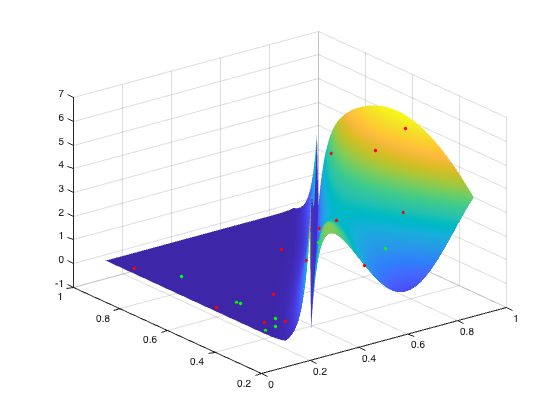

[xn,yn,sn] = create_samples(X,Y,Space,[row col]);

draw_samples(X,Y,Space,x,y,s,xn,yn,sn);

The samples are placed in the flat area of the function.

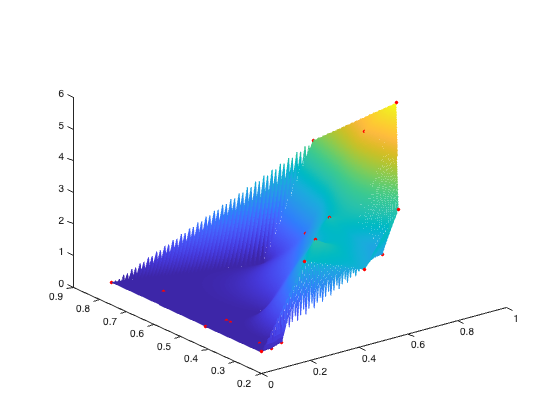

draw_interpolation(X,Y,cat(2,x,xn),cat(2,y,yn),cat(2,s,sn));

### BFF WITH RANDOM SAMPLING

% % Sampling weight
% 
% weight_mat = zeros(size(Space));
% % Check also `find` and `ismember`
% for ii = 1:size(Space,1)
%     for jj = 1:size(Space,2)
%         % ii -> rows, jj -> columns
%         % If it is not a pivot
%         if sum(ismember(samples,[ii jj],'rows')) ~= 1
%             weight = 0;
%             for i = 1:budget
%                 if samples(i,1) == ii || samples(i,2) == jj
%                     weight = weight + criticality_BFF(i);
%                 end
%             end
%         else
%             weight = 0;
%         end
%         weight_mat(ii,jj) = weight;
%     end
% end
% 
% % Sampling probability
% 
% total_sum = sum(weight_mat, "all");
% prob_mat = ((1-alpha) .* weight_mat) ./ total_sum;
% 
% card = numel(Space);
% not_aligned = card - nnz(weight_mat) + budget;
% 
% for ii = 1:size(Space,1)
%     for jj = 1:size(Space,2)
%         % ii -> rows, jj -> columns
%         % If it is not a pivot
%         if sum(ismember(samples,[ii jj],'rows')) ~= 1
%             if prob_mat(ii,jj) == 0
%                 prob_mat(ii,jj) = alpha / (card-not_aligned);
%             end
%         end
%     end
% end
% 
% contour(X,Y,prob_mat)
% mesh(X,Y,prob_mat)
% new_samples = maxk(prob_mat,new_budget);
% [maxvalues,ind] = maxk(prob_mat(:),new_budget);
% [row,col] = ind2sub(size(prob_mat),ind);
% 
% [row col maxvalues]

With random sampling, the new samples are exactly the same. This may also be due to the size of the space or may also be influenced by the $\alpha$ parameter.

### GOOD FIT FIRST

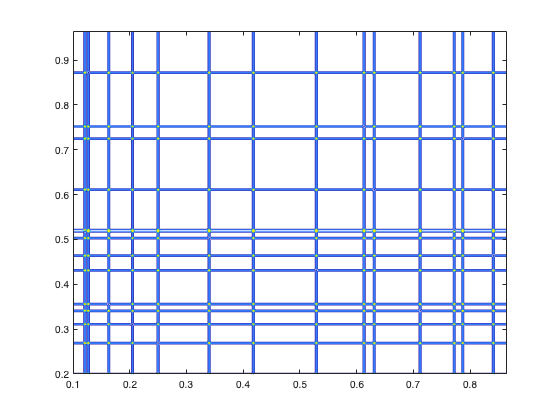

[row,col,maxvalues,losses,prob_mat] = create_new_samples(X,Y,Space, ...
    T_full,tensor_recon,samples, ...
    new_budget,'gff');
contour(X,Y,prob_mat)

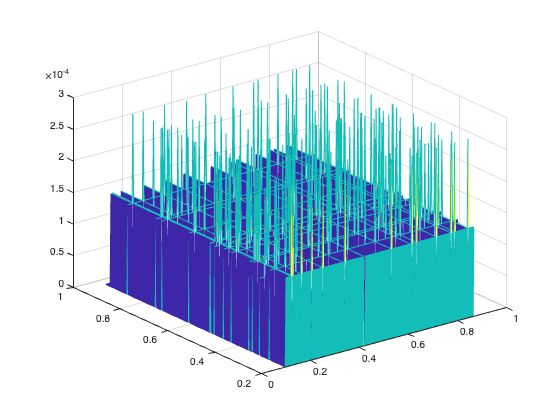

mesh(X,Y,prob_mat)

disp(losses')

      0.99999
      0.98599
            1
            1
      0.85827
            1
            1
            1
      0.98175
            1
            1
            1
      0.99314
            1



[row col maxvalues]

ans =             1           51   0.00028378
           48           51   0.00028378
           78           51   0.00028378
           89           51   0.00028378
          108           51   0.00028378
          138           51   0.00028378
          176           51   0.00028378
           24          107   0.00028378


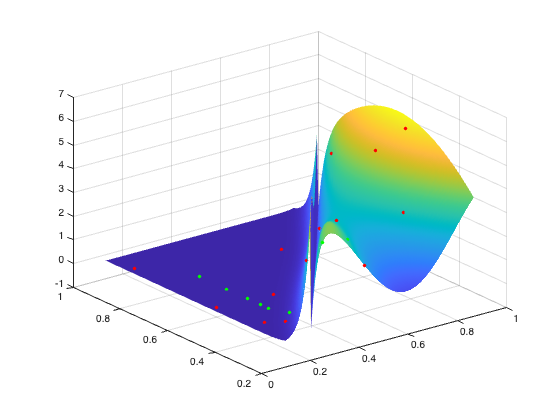

[xn,yn,sn] = create_samples(X,Y,Space,[row col]);

draw_samples(X,Y,Space,x,y,s,xn,yn,sn);

In this case the samples are more spread out.

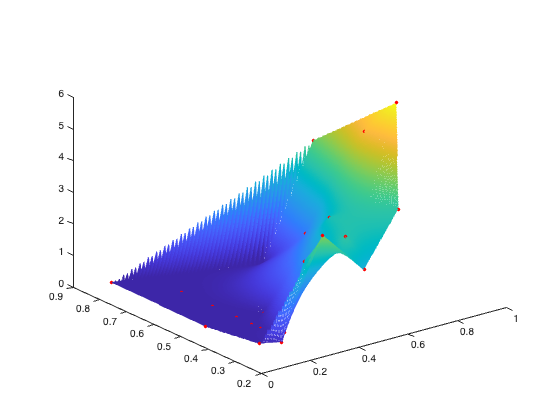

draw_interpolation(X,Y,cat(2,x,xn),cat(2,y,yn),cat(2,s,sn));

### GFF WITH RANDOM SAMPLING

% % Sampling weight
% 
% weight_mat = zeros(size(Space));
% % Check also `find` and `ismember`
% for ii = 1:size(Space,1)
%     for jj = 1:size(Space,2)
%         % ii -> rows, jj -> columns
%         % If it is not a pivot
%         if sum(ismember(samples,[ii jj],'rows')) ~= 1
%             weight = 0;
%             for i = 1:budget
%                 if samples(i,1) == ii || samples(i,2) == jj
%                     weight = weight + criticality_GFF(i);
%                 end
%             end
%         else
%             weight = 0;
%         end
%         weight_mat(ii,jj) = weight;
%     end
% end
% 
% % Sampling probability
% 
% total_sum = sum(weight_mat, "all");
% prob_mat = ((1-alpha) .* weight_mat) ./ total_sum;
% 
% card = numel(Space);
% not_aligned = card - nnz(weight_mat) + budget;
% 
% for ii = 1:size(Space,1)
%     for jj = 1:size(Space,2)
%         % ii -> rows, jj -> columns
%         % If it is not a pivot
%         if sum(ismember(samples,[ii jj],'rows')) ~= 1
%             if prob_mat(ii,jj) == 0
%                 prob_mat(ii,jj) = alpha / (card-not_aligned);
%             end
%         end
%     end
% end
% 
% contour(X,Y,prob_mat)
% mesh(X,Y,prob_mat)
% new_samples = maxk(prob_mat,new_budget);
% [maxvalues,ind] = maxk(prob_mat(:),new_budget);
% [row,col] = ind2sub(size(prob_mat),ind);
% 
% [row col maxvalues]

Here the new samples are slightly different from the version without random sampling, although the $\alpha$ parameter should also be adjusted.

% x2 = zeros(1,new_budget);
% y2 = zeros(1,new_budget);
% s2 = zeros(1,new_budget);
% for i = 1:new_budget
%     x2(i) = X(row(i),col(i));
%     y2(i) = Y(row(i),col(i));
%     s2(i) = Space(row(i),col(i));
% end
% 
% surf(X,Y,Space,'EdgeColor','none')
% hold on
% plot3(x,y,s,'.r','markersize',10)
% hold on
% plot3(x2,y2,s2,'.g','markersize',10)
% hold off
% nx = cat(2,x,x2);
% ny = cat(2,y,y2);
% ns = cat(2,s,s2);
% z = griddata(nx,ny,ns,X,Y,"natural");
% plot3(nx,ny,ns,'.r','markersize',10)
% hold on
% mesh(X,Y,z)
% hold off